# Introduction to SpinW

SpinW (*spin-double-u*) is a Matlab library that can optimize magnetic structures using mean field theory and calculate spin wave dispersion and spin-spin correlation function for complex crystal and magnetic structures.

In this introduction we will give the canonical example of a Ferromagnetic Spin Chain

## The spin chain

### Introduction

The spin chain is one of the first examples student come across when introduced  to linear spin wave theory. This is because it has an analytical  solution and can be done in the period of a lecture. Remembering those days (and hopefully not bringing back painful memories of operators) we will work though the solution using SpinW, which I promise will be easier. The hamiltonian for the spin chain is


$${\cal H} = \sum_i J_x S_i^x S_{i+1}^x + J_y S_i^y S_{i+1}^y + J_z S_i^z S_{i+1}^z$$


But, we're going to set $J_y$ and $J_z$ to be 0.

We create a SpinW object

FMchain = spinw

FMchain =      SpinW object, spinw class:
     Chemical formula: 
     Space group:      P 0
     Lattice:
       a= 3.0000 Å, b= 3.0000 Å, c= 3.0000 Å
       α= 90.00°,   β= 90.00°,   γ= 90.00°
     Magnetic atoms in the unit cell: 0
     Mode:
       symbolic: off, symmetry: off, textoutput: "stdout"

And can now modify it to create a spin chain as described by the Hamiltonian above.

### Creating the Lattice

Since  this is toy model we will create a lattice with two cell lengths longer than the other. This shorter cell length will be where the chain will be formed as it will be the shortest distace for interactions.

FMchain.genlattice('lat_const',[3 8 8],'angled',[90 90 90])

Now an atom with spin 1 is placed at the fractional coordinate (0, 0, 0)

FMchain.addatom('r', [0 0 0],'S', 1,'label','MCu1','color','blue')

We can easily visualise this 

Creating 3D plot... 


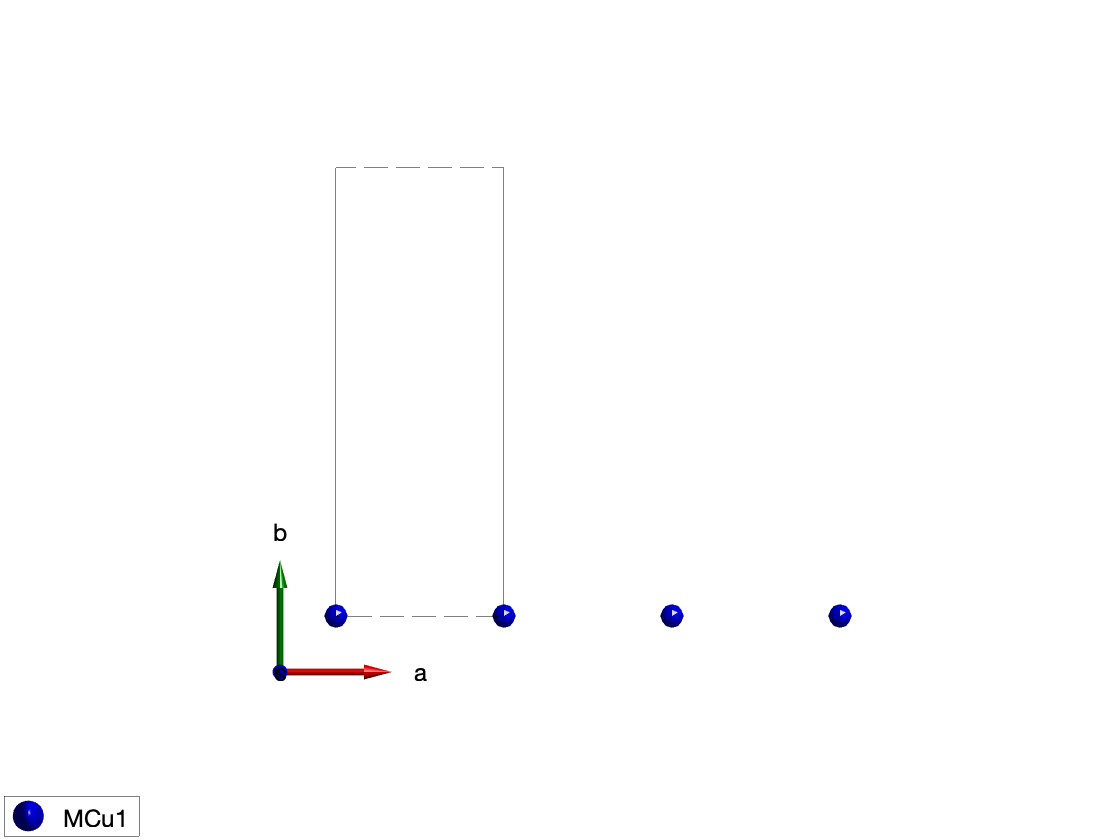

...2k faces and 1k vertices are drawn!


plot(FMchain)

### Creating the Interactions

Interactions can be generated by the code. As we can see, the generated interactions (nearest neighbour and next nearest neighbour) are along *a* the shortest cell length.

FMchain.gencoupling('maxDistance',7)

Creating the bond list (maxDistance = 7 Å, nCell = 3x1x1)...
...2 bonds are retained out of 36 generated!


FMchain.table('bond',1:2)

ans = 2×10 table
    idx    subidx        dl             dr         length     matom1     idx1     matom2     idx2                    matrix                
    ___    ______    ___________    ___________    ______    ________    ____    ________    ____    ______________________________________

     1       1       1    0    0    1    0    0      3       {'MCu1'}     1      {'MCu1'}     1      {0×0 char}    {0×0 char}    {0×0 char}
     2       1       2    0    0    2    0    0      6       {'MCu1'}     1      {'MCu1'}     1      {0×0 char}    {0×0 char}    {0×0 char}


Now that the interactions are generated, we can assign values to them. In this case we will only do the nearest ineraction

FMchain.addmatrix('value',-eye(3),'label','Ja','color','green')
FMchain.addcoupling('mat','Ja','bond',1);

We can see that it does indeed look like a chain!

Creating 3D plot... 


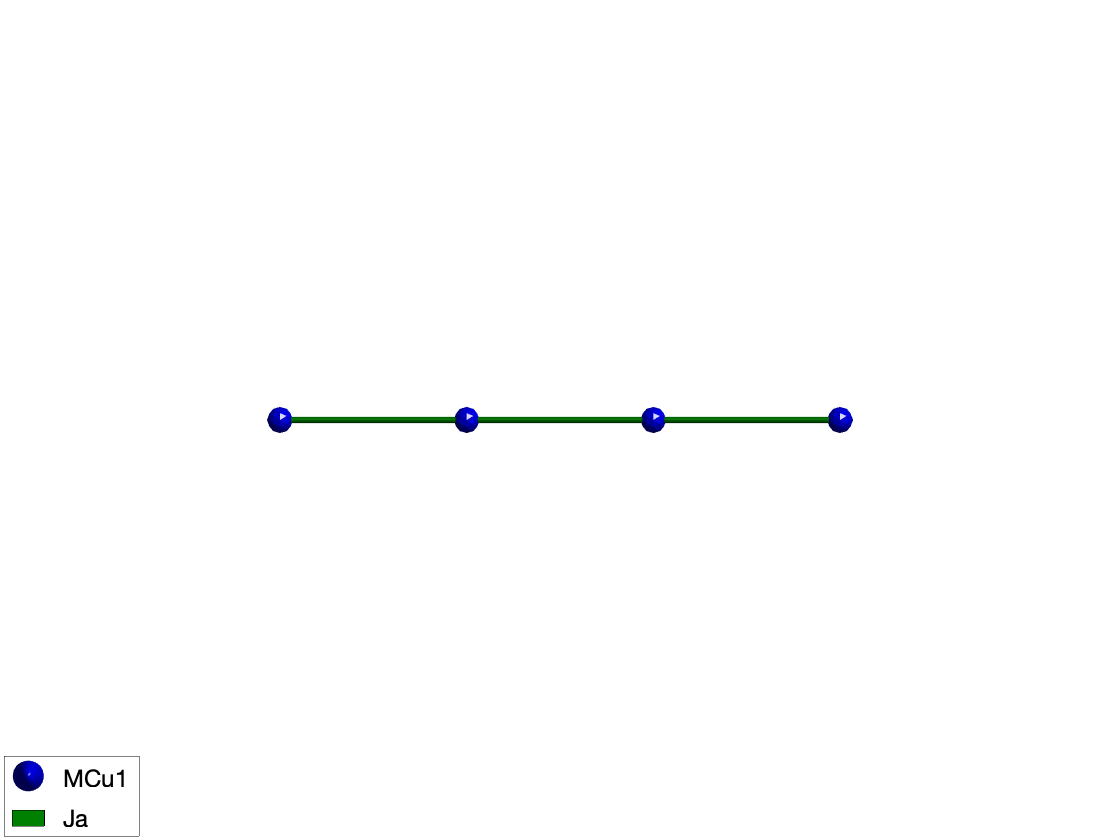

...2k faces and 1k vertices are drawn!


plot(FMchain,'range',[3 0.2 0.2],'cellMode','none','baseMode','none')

### Creating the magnetic structure

The classical magnetic ground state of the previously defined Hamiltonian is where every spin have the same direction, the direction is arbitrary since the Hamiltonian is isotropic. We use the following parameters:

- magnetic ordering wave vector k = (0 0 0)

- there is a single spin per unit cell S = [0 1 0]

- an arbitrary normal vector to the spin n = [1 0 0]

Creating 3D plot... 


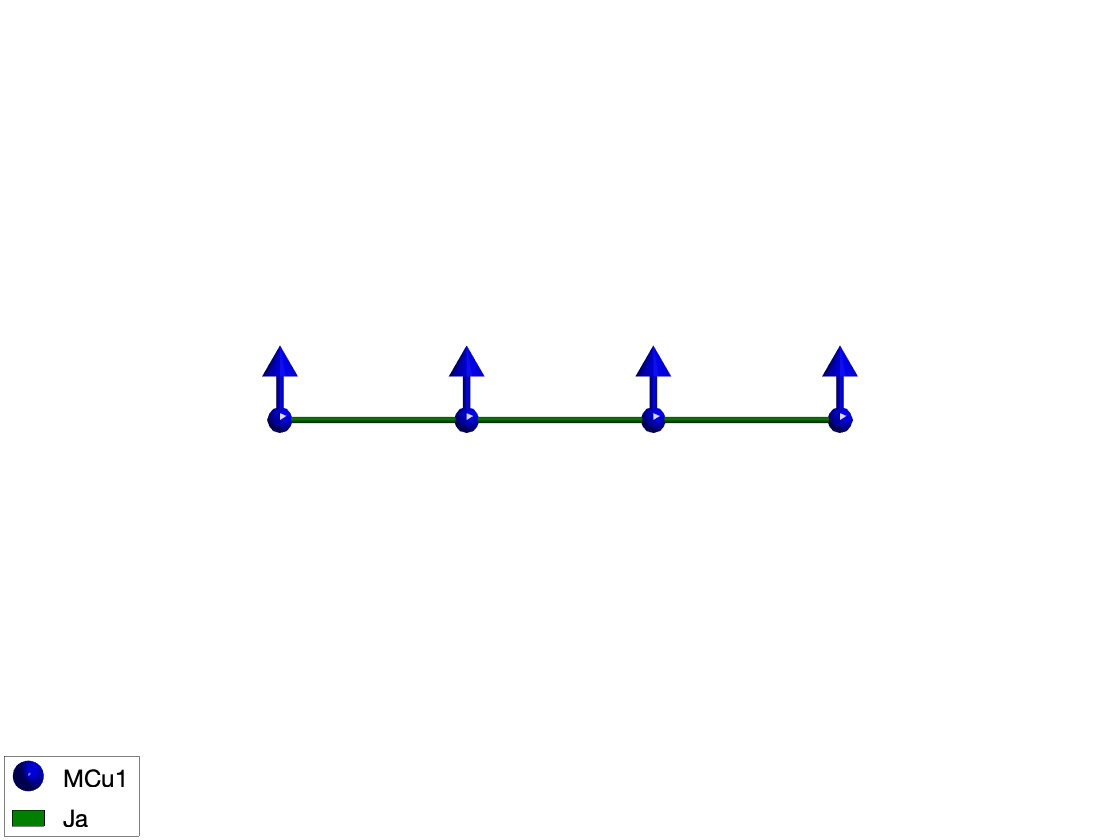

...2k faces and 1k vertices are drawn!


FMchain.genmagstr('mode','direct', 'k',[0 0 0],'n',[1 0 0],'S',[0; 1; 0]);
plot(FMchain,'range',[3 0.9 0.9],'baseMode','none','cellMode','none')

**We have now described the Hamiltonian of a spin chain.**

## The energy of the ground state per spin

Using the SpinW object, we can obtain the ground state energy per spin

FMchain.energy

Ground state energy: -1.000 meV/spin.


As we can see, it's the value -1, which we expect from the theory

## Calculate spin wave dispersion and spin-spin correlation function

Now the interesting part. We calculate spin wave dispersion and correlation function along the chain. In this case the chain will disperse along the momentum transfer value is* Q = (H 0 0).* 

FMspec = FMchain.spinwave({[0 0 0] [1 0 0]},'hermit',false);

Calculating COMMENSURATE spin wave spectra (nMagExt = 1, nHkl = 100, nTwin = 1)...
No magnetic form factor is included in the calculated structure factor.
No g-tensor is included in the calculated structure factor.
Calculation is finished in 00:00:00 (hh:mm:ss).
Calculation finished.


This calculates the spin-spin correlations. However we are interested in the the neutron scattering cross section and select '*Sperp*' the neutron scattering intensity for plotting. 

FMspec = sw_neutron(FMspec);
FMspec = sw_egrid(FMspec,'component','Sperp');

Then we plot spin wave dispersion and the value of the correlation function with the 1-Q^2 neutron scattering cross section in units of hbar/spin.

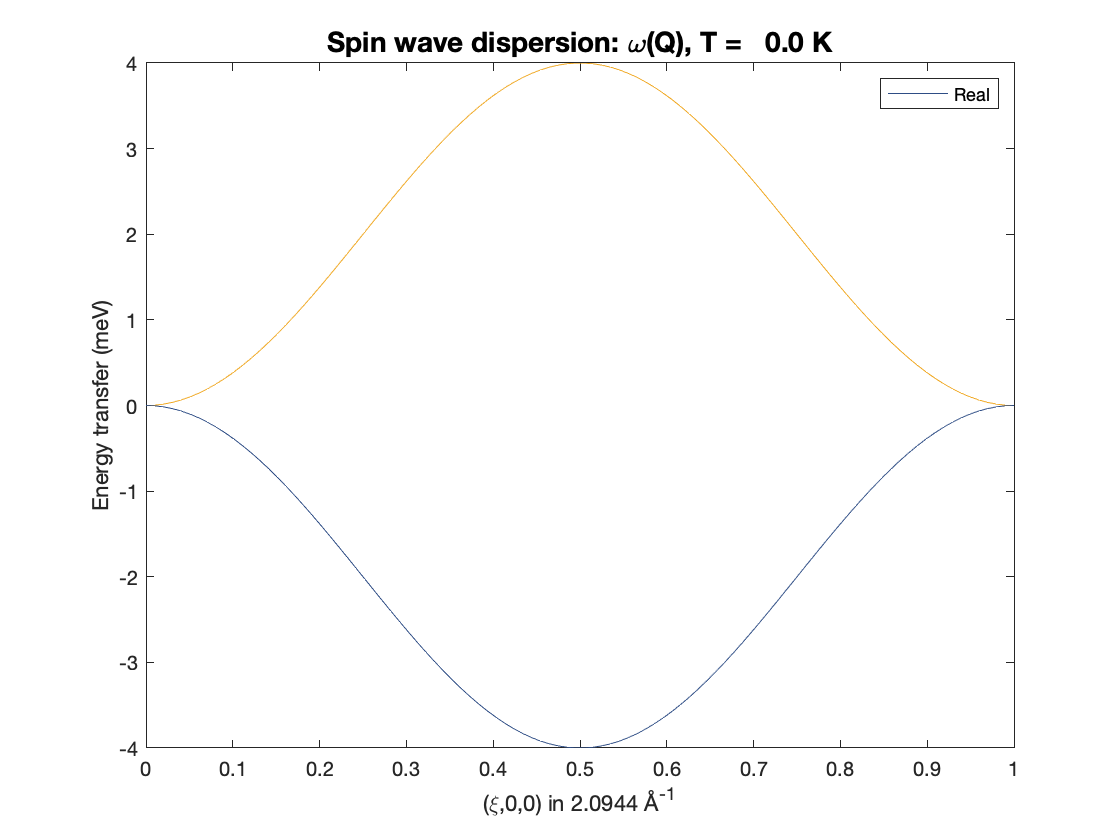

figure;
sw_plotspec(FMspec,'mode',1,'colorbar',false)